%% General CSV Waveform Plotter
% Assumes:
%   - Column 1 is Time
%   - Columns 2:end are waveform data
%   - Existing CSV column names are used for plot labels/titles

clear; clc; close all;

%% LTspice Default Colors

Color1  = [0   255   0] / 255;      % Green
Color2  = [0     0 255] / 255;      % Blue
Color3  = [255   0   0] / 255;      % Red
Color4  = [0   192 192] / 255;      % Cyan
Color5  = [255   0 255] / 255;      % Magenta
Color6  = [128 128 128] / 255;      % Gray
Color7  = [0   128   0] / 255;      % Dark Green
Color8  = [0     0 128] / 255;      % Dark Blue
Color9  = [192 160   0] / 255;      % Gold
Color10 = [128   0 128] / 255;      % Purple
Color11 = [128   0   0] / 255;      % Dark Red
Color12 = [160 160   0] / 255;      % Olive

ColorList = { ...
    Color1, Color2, Color3, Color4, ...
    Color5, Color6, Color7, Color8, ...
    Color9, Color10, Color11, Color12};

%% LTspice Plot Appearance

FigureColor = [0 0 0];
AxesColor   = [0 0 0];
TextColor   = [1 1 1];
GridColor   = [0.4 0.4 0.4];

%% Select CSV file

[file,path] = uigetfile('*.csv','Select waveform CSV file');

if isequal(file,0)
    error('No file selected.');
end

csvFile = fullfile(path,file);

%% Read CSV while preserving column names

T = readtable(csvFile,'VariableNamingRule','preserve');

time = T{:,1};
timeName = T.Properties.VariableNames{1};

signalNames = T.Properties.VariableNames(2:end);
numSignals = numel(signalNames);

fprintf('Loaded file: %s\n',csvFile);

Loaded file: C:\Users\jayse\OneDrive - Virginia Tech\Documents\LTspice\Stage2bLM2596Model(SS3P5)-3A.csv


fprintf('Time column: %s\n',timeName);

Time column: Time


fprintf('Detected %d waveform columns.\n',numSignals);

Detected 4 waveform columns.



%% Choose time scaling

fprintf('\nChoose time axis unit:\n');


Choose time axis unit:


fprintf('1 = seconds\n');

1 = seconds


fprintf('2 = milliseconds\n');

2 = milliseconds


fprintf('3 = microseconds\n');

3 = microseconds


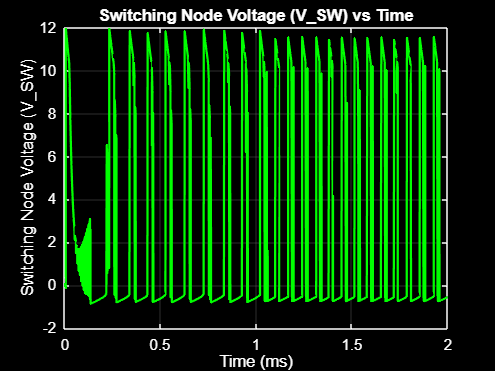

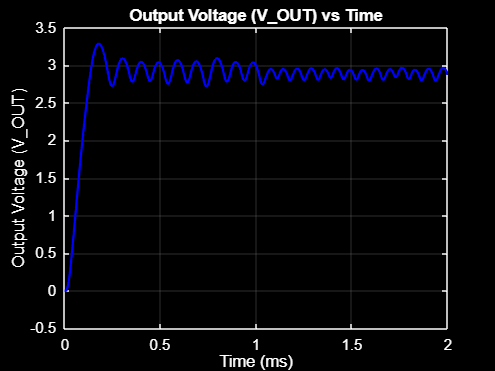

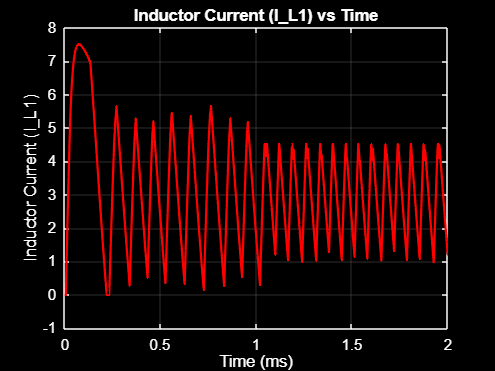

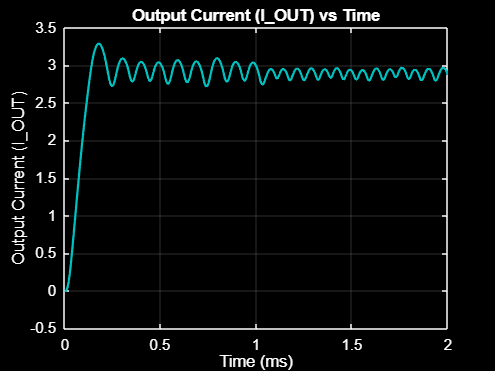


timeChoice = input('Selection: ');

switch timeChoice
    case 1
        timeScale = 1;
        timeLabel = 'Time (s)';
    case 2
        timeScale = 1e3;
        timeLabel = 'Time (ms)';
    case 3
        timeScale = 1e6;
        timeLabel = 'Time (\mus)';
    otherwise
        warning('Invalid choice. Using seconds.');
        timeScale = 1;
        timeLabel = 'Time (s)';
end

tPlot = time * timeScale;

%% Create output folder

[~,baseName,~] = fileparts(file);
outputDir = fullfile(path,[baseName '_plots']);

if ~exist(outputDir,'dir')
    mkdir(outputDir);
end

%% Plot each waveform individually

for k = 1:numSignals

    sigName = signalNames{k};
    y = T{:,k+1};

    colorIndex = mod(k-1,length(ColorList)) + 1;
    traceColor = ColorList{colorIndex};

    figure;
    set(gcf,'Color',FigureColor);

    plot(tPlot,y,...
        'LineWidth',1.5,...
        'Color',traceColor);

    ax = gca;

    ax.Color = AxesColor;
    ax.XColor = TextColor;
    ax.YColor = TextColor;
    ax.GridColor = GridColor;
    ax.GridAlpha = 0.3;

    grid on;

    xlabel(timeLabel,...
        'Color',TextColor);

    ylabel(sigName,...
        'Interpreter','none',...
        'Color',TextColor);

    title([sigName ' vs Time'],...
        'Interpreter','none',...
        'Color',TextColor);

    safeFileName = matlab.lang.makeValidName(sigName);

    saveas(gcf,...
        fullfile(outputDir,...
        [safeFileName '_vs_time.png']));
end

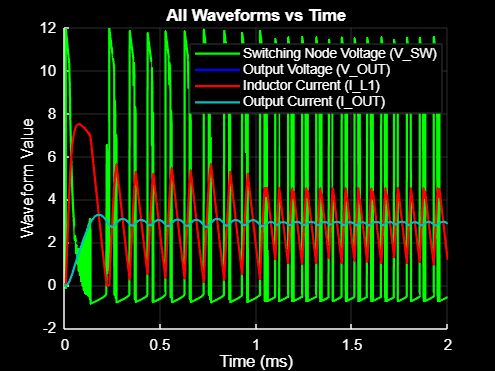


%% Plot all waveforms together

figure;
set(gcf,'Color',FigureColor);

hold on;
grid on;

for k = 1:numSignals

    sigName = signalNames{k};
    y = T{:,k+1};

    colorIndex = mod(k-1,length(ColorList)) + 1;
    traceColor = ColorList{colorIndex};

    plot(tPlot,y,...
        'LineWidth',1.5,...
        'Color',traceColor,...
        'DisplayName',sigName);

end

ax = gca;

ax.Color = AxesColor;
ax.XColor = TextColor;
ax.YColor = TextColor;
ax.GridColor = GridColor;
ax.GridAlpha = 0.3;

xlabel(timeLabel,...
    'Color',TextColor);

ylabel('Waveform Value',...
    'Color',TextColor);

title('All Waveforms vs Time',...
    'Color',TextColor);

lgd = legend('Location','best',...
             'Interpreter','none');

lgd.TextColor = TextColor;
lgd.Color = FigureColor;

saveas(gcf,...
    fullfile(outputDir,...
    'all_waveforms_vs_time.png'));


%% Select Time Window for Zoomed Plots

fprintf('\nOptional zoomed time-window plots.\n');


Optional zoomed time-window plots.



Enter time window using the same unit selected earlier.



Current time-step information in selected zoom window:


Minimum time step: 3.95204e-09 (ms)


Maximum time step: 0.0001 (ms)


Mean time step:    3.4162e-05 (ms)


Median time step:  1.94262e-06 (ms)


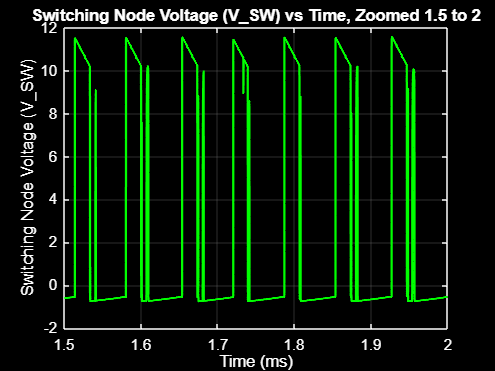

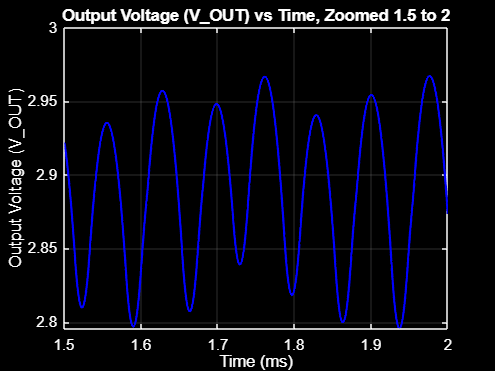

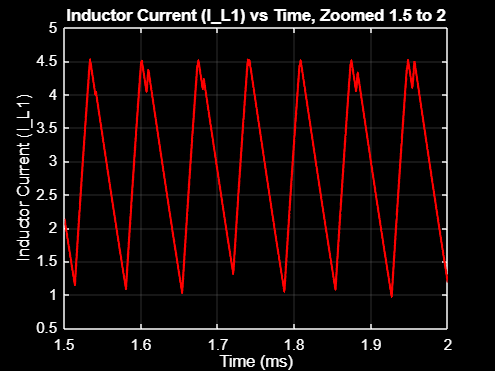

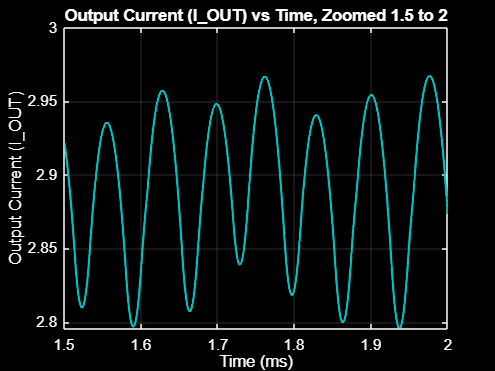

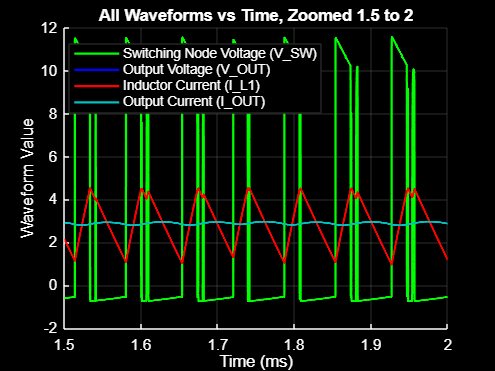

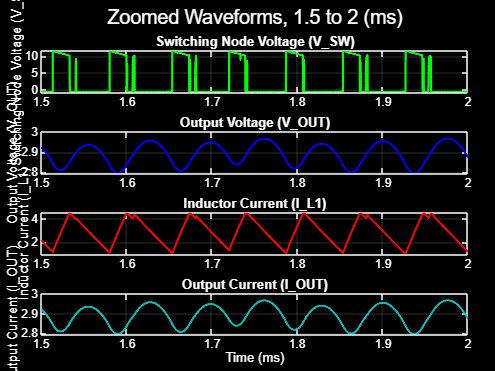


Zoomed plots saved to:
C:\Users\jayse\OneDrive - Virginia Tech\Documents\LTspice\Stage2bLM2596Model(SS3P5)-3A_plots\zoomed_plots


makeZoomPlots = input('Create zoomed plots? 1 = yes, 0 = no: ');

if makeZoomPlots == 1

    fprintf('\nEnter time window using the same unit selected earlier.\n');
    tStartInput = input('Start time: ');
    tEndInput   = input('End time: ');

    tStart = tStartInput / timeScale;
    tEnd   = tEndInput   / timeScale;

    idxZoom = time >= tStart & time <= tEnd;

    if ~any(idxZoom)
        warning('No data found in selected time window. Skipping zoomed plots.');
    else

        tZoom = time(idxZoom) * timeScale;

        %% Display Current Time-Step Information

        dtZoom = diff(time(idxZoom));
        dtZoomPlotUnits = dtZoom * timeScale;

        fprintf('\nCurrent time-step information in selected zoom window:\n');
        fprintf('Minimum time step: %.6g %s\n', min(dtZoomPlotUnits), erase(timeLabel,'Time '));
        fprintf('Maximum time step: %.6g %s\n', max(dtZoomPlotUnits), erase(timeLabel,'Time '));
        fprintf('Mean time step:    %.6g %s\n', mean(dtZoomPlotUnits), erase(timeLabel,'Time '));
        fprintf('Median time step:  %.6g %s\n', median(dtZoomPlotUnits), erase(timeLabel,'Time '));

        %% Optional Time Resampling

        useCustomStep = input('\nUse custom time step for zoomed plots? 1 = yes, 0 = no: ');

        if useCustomStep == 1
            customStepInput = input('Enter desired time step using selected time unit: ');
            customStepSeconds = customStepInput / timeScale;

            tUniformSeconds = (tStart:customStepSeconds:tEnd).';
            xZoom = tUniformSeconds * timeScale;

            useResampledData = true;
        else
            tUniformSeconds = time(idxZoom);
            xZoom = tZoom;

            useResampledData = false;
        end

        zoomDir = fullfile(outputDir,'zoomed_plots');

        if ~exist(zoomDir,'dir')
            mkdir(zoomDir);
        end

        %% Zoomed individual plots

        for k = 1:numSignals

            sigName = signalNames{k};

            if useResampledData
                yOriginal = T{idxZoom,k+1};
                tOriginal = time(idxZoom);
                yZoom = interp1(tOriginal, yOriginal, tUniformSeconds, 'linear');
            else
                yZoom = T{idxZoom,k+1};
            end

            colorIndex = mod(k-1,length(ColorList)) + 1;
            traceColor = ColorList{colorIndex};

            figure;
            set(gcf,'Color',FigureColor);

            plot(xZoom,yZoom,...
                'LineWidth',1.5,...
                'Color',traceColor);

            ax = gca;
            ax.Color = AxesColor;
            ax.XColor = TextColor;
            ax.YColor = TextColor;
            ax.GridColor = GridColor;
            ax.GridAlpha = 0.3;

            grid on;

            xlabel(timeLabel,'Color',TextColor);
            ylabel(sigName,'Interpreter','none','Color',TextColor);

            title(sprintf('%s vs Time, Zoomed %.3g to %.3g', ...
                sigName, tStartInput, tEndInput), ...
                'Interpreter','none',...
                'Color',TextColor);

            safeFileName = matlab.lang.makeValidName(sigName);

            saveas(gcf,...
                fullfile(zoomDir,...
                [safeFileName '_zoomed_vs_time.png']));
        end

        %% Zoomed combined plot

        figure;
        set(gcf,'Color',FigureColor);

        hold on;
        grid on;

        for k = 1:numSignals

            sigName = signalNames{k};

            if useResampledData
                yOriginal = T{idxZoom,k+1};
                tOriginal = time(idxZoom);
                yZoom = interp1(tOriginal, yOriginal, tUniformSeconds, 'linear');
            else
                yZoom = T{idxZoom,k+1};
            end

            colorIndex = mod(k-1,length(ColorList)) + 1;
            traceColor = ColorList{colorIndex};

            plot(xZoom,yZoom,...
                'LineWidth',1.5,...
                'Color',traceColor,...
                'DisplayName',sigName);
        end

        ax = gca;
        ax.Color = AxesColor;
        ax.XColor = TextColor;
        ax.YColor = TextColor;
        ax.GridColor = GridColor;
        ax.GridAlpha = 0.3;

        xlabel(timeLabel,'Color',TextColor);
        ylabel('Waveform Value','Color',TextColor);

        title(sprintf('All Waveforms vs Time, Zoomed %.3g to %.3g', ...
            tStartInput, tEndInput), ...
            'Color',TextColor);

        lgd = legend('Location','best','Interpreter','none');
        lgd.TextColor = TextColor;
        lgd.Color = FigureColor;

        saveas(gcf,...
            fullfile(zoomDir,...
            'all_waveforms_zoomed_vs_time.png'));

        %% Zoomed stacked subplots

        figure;
        set(gcf,'Color',FigureColor);

        tiledlayout(numSignals,1,'TileSpacing','compact','Padding','compact');

        for k = 1:numSignals

            sigName = signalNames{k};

            if useResampledData
                yOriginal = T{idxZoom,k+1};
                tOriginal = time(idxZoom);
                yZoom = interp1(tOriginal, yOriginal, tUniformSeconds, 'linear');
            else
                yZoom = T{idxZoom,k+1};
            end

            colorIndex = mod(k-1,length(ColorList)) + 1;
            traceColor = ColorList{colorIndex};

            nexttile;

            plot(xZoom,yZoom,...
                'LineWidth',1.5,...
                'Color',traceColor);

            ax = gca;
            ax.Color = AxesColor;
            ax.XColor = TextColor;
            ax.YColor = TextColor;
            ax.GridColor = GridColor;
            ax.GridAlpha = 0.3;

            grid on;

            ylabel(sigName,'Interpreter','none','Color',TextColor);
            title(sigName,'Interpreter','none','Color',TextColor);
        end

        xlabel(timeLabel,'Color',TextColor);

        sgtitle(sprintf('Zoomed Waveforms, %.3g to %.3g %s', ...
            tStartInput, tEndInput, erase(timeLabel,'Time ')), ...
            'Color',TextColor);

        saveas(gcf,...
            fullfile(zoomDir,...
            'zoomed_waveforms_stacked_subplots.png'));

        fprintf('\nZoomed plots saved to:\n%s\n',zoomDir);
    end
end


fprintf('\nCreated %d individual plots and 1 combined plot.\n',numSignals);


Created 4 individual plots and 1 combined plot.


fprintf('Plots saved to:\n%s\n',outputDir);

Plots saved to:
C:\Users\jayse\OneDrive - Virginia Tech\Documents\LTspice\Stage2bLM2596Model(SS3P5)-3A_plots
